# Stock Market Data Analysis and Visualisation Tool

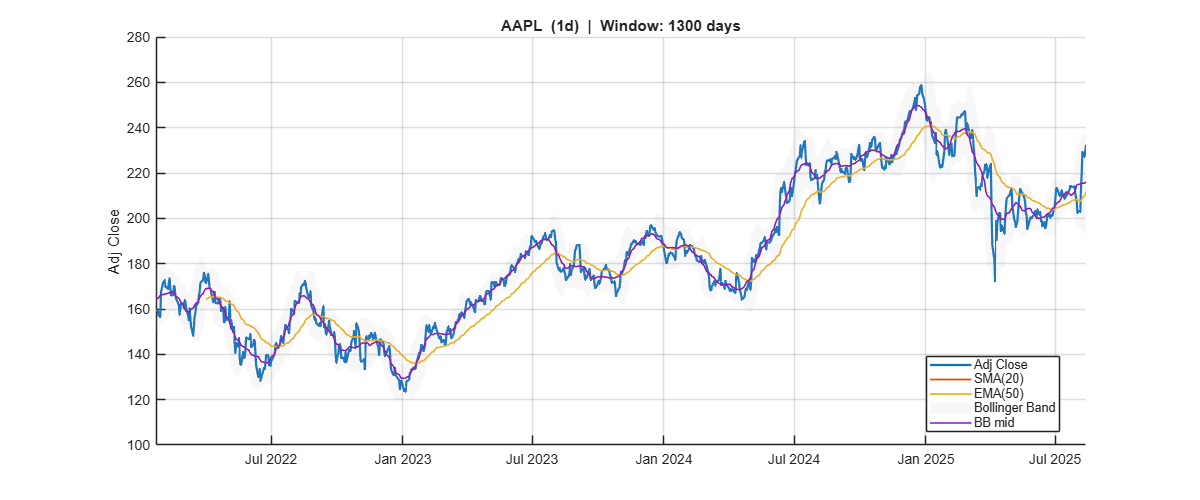

% HOW TO USE
% -----------
% 1. At the very top of this script, you'll see Live Editor controls:
%      - ticker            (Edit Field Text, e.g., "AAPL")
%      - interval          (Dropdown: ["1d", "1wk", "1mo"])
%      - showLastNDays     (Slider: choose history length to fetch and analyze)
%      - forecastHorizon   (Dropdown: ["1M", "3M", "6M", "1Y", "2Y"])
%      - longevity         (Dropdown: ["Short", "Medium", "Long"])
% 
% 2. Change any of these and click "Run Section" (or enable "Rerun on value change").
%    The script will automatically:
%       - Download historical OHLCV data from Stooq (no API key needed)
%       - Build predictive features and run the forecast
%       - Smooth and label the predicted market direction
%       - Backtest the model over recent history
%
% 3. Read the results:
%       - The first chart shows price history + SMA/EMA/Bollinger + RSI
%       - The forecast chart shows predicted closes, smoothed direction,
%         and "flip points" (where the model changes from up to down or vice versa)
%       - The backtest chart compares model equity vs. buy & hold, 
%         with Sharpe ratio, hit rate, and max drawdown printed in the console
%
% WHAT THE SCRIPT DOES
% --------------------
% • Features: SMA distance, Bollinger position, RSI, EMA/SMA relation,
%   realized volatility, MACD, ATR, and Kalman-filtered drift
% • Model: Ensemble of ridge regression and logistic regression with
%   automatic hyperparameter tuning
% • Forecast: Step-by-step rollout to the chosen horizon
% • Backtest: Walk-forward simulation with adaptive thresholding
%
% NOTES
% -----
% • This is an educational tool for exploring time series forecasting and 
%   technical indicators — it is NOT trading advice.
% • If you get "Not enough data" errors, increase `showLastNDays` or use a shorter interval.
% • Results will vary based on chosen parameters, asset volatility, and history length.


ticker = "AAPL";
interval = "1d";
showLastNDays =1300;
forecastHorizon = "2Y";
longevity = "Medium";

% --- Bind & sanitize controls (keeps Live Editor happy) ---
if ~exist('ticker','var') || strlength(string(ticker))==0, ticker = "TSLA"; end
ticker   = string(strtrim(ticker));
if ~exist('interval','var') || strlength(string(interval))==0, interval = "1d"; end
interval = string(lower(strtrim(interval)));
if interval=="1w", interval="1wk"; end
if ~ismember(interval,["1d","1wk","1mo"]), interval="1d"; end

if ~exist('showLastNDays','var') || ~isscalar(showLastNDays) || ~isfinite(showLastNDays)
    showLastNDays = 1000;
end
showLastNDays = max(90, round(double(showLastNDays)));

if ~exist('forecastHorizon','var') || strlength(string(forecastHorizon))==0
    forecastHorizon = "6M";
end
forecastHorizon = string(upper(strtrim(forecastHorizon)));
if ~ismember(forecastHorizon,["1M","3M","6M","1Y","2Y"]), forecastHorizon="6M"; end

if ~exist('longevity','var') || strlength(string(longevity))==0
    longevity = "Medium";
end
longevity = string(strtrim(longevity));
if ~ismember(longevity,["Short","Medium","Long"]), longevity="Medium"; end

% --- Internal fixed parameters ---
modelType       = "ensemble";  % ensemble (ridge + logistic)
lagsSpec        = [1 5 20];    % feature lags (days)
tradeThresh     = 0.55;        % probability threshold for backtest trades
tradeCostBps    = 2;           % round-trip cost in basis points
kalmanVarProc   = 1e-6;        % process noise for Kalman drift
kalmanVarObs    = 1e-4;        % observation noise for Kalman drift

% ---------- Fetch historical OHLCV ----------
startDT = datetime(2015,1,1);
endDT   = datetime('today');
T = getHistory(ticker, startDT, endDT, interval);
if isempty(T)
    error("No data returned for '%s' (%s). Try a different symbol or interval.", ticker, interval);
end

% Restrict window
cutDate = max(T.Date) - days(showLastNDays);
T = T(T.Date >= cutDate, :);
if height(T) < 10
    error("Not enough data in the selected window. Increase 'showLastNDays'.");
end

% ---------- Indicators for visuals ----------
closeP = T.AdjClose;
SMA20  = movmean(closeP, 20, 'omitnan');
EMA50  = ema_simple(closeP, 50);
[BBmid, BBlow, BBup] = boll_bands(closeP, 20, 2);
RSI14  = rsi_simple(closeP, 14);

% ---------- Forecast with upgraded ML ----------
[futureDates, dirRaw, dirSmoothed, probUp, model, varNames] = ...
    forecast_direction_upgraded(T, interval, forecastHorizon, longevity, ...
                                modelType, lagsSpec, kalmanVarProc, kalmanVarObs);
% Clean / sort futureDates for plotting
futureDates = futureDates(:);
futureDates = futureDates(~isnat(futureDates));
if numel(futureDates) < 2
    % make a minimal 2-point span after last date to keep plots happy
    futureDates = [T.Date(end)+days(1); T.Date(end)+days(2)];
end


% ---------- Backtest ----------
R = backtest_walkforward(T, modelType, lagsSpec, model.lambda, tradeThresh, tradeCostBps, ...
                         kalmanVarProc, kalmanVarObs, interval);

% =============================================================================
%                                P L O T S
% =============================================================================

% ---------- Price + SMA/EMA + Bollinger ----------
hfig1 = getOrCreateFig("Price & Bands", [100 100 1200 500]);
ax1   = getOrCreateAxes(hfig1, "axPrice");
grid(ax1,'on'); hold(ax1,'on');
plot(ax1, T.Date, closeP, 'LineWidth',1.6, 'DisplayName','Adj Close');
plot(ax1, T.Date, SMA20,  'LineWidth',1.2, 'DisplayName','SMA(20)');
plot(ax1, T.Date, EMA50,  'LineWidth',1.2, 'DisplayName','EMA(50)');
[px,py] = bandPolygon(T.Date, BBlow, BBup);
patch(ax1, px, py, [0.7 0.7 0.7], 'FaceAlpha',0.10, 'EdgeColor','none', 'DisplayName','Bollinger Band');
plot(ax1, T.Date, BBmid,  'LineWidth',1.0, 'DisplayName','BB mid');
ylabel(ax1,'Adj Close');
safeXLim(ax1, T.Date);
title(ax1, sprintf('%s  (%s)  |  Window: %d days', upper(string(ticker)), interval, showLastNDays));
legend(ax1,'Location','best');

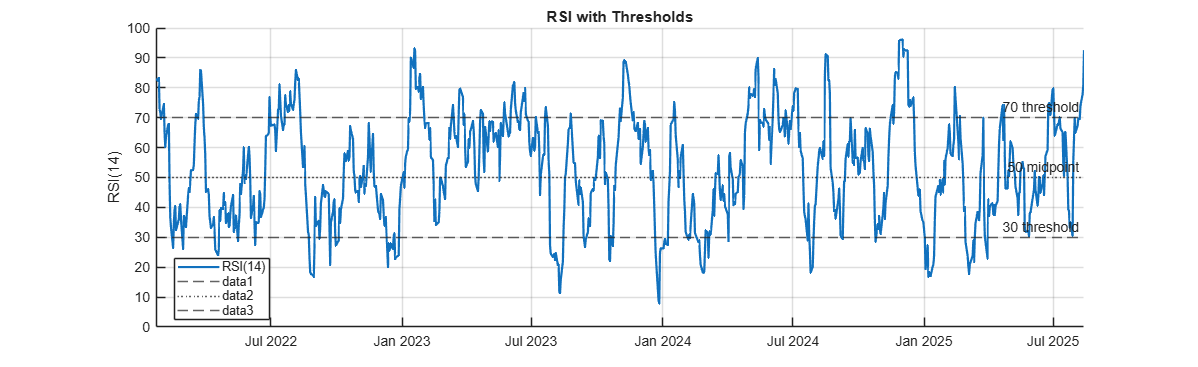


% ---------- RSI ----------
hfig2 = getOrCreateFig("RSI", [150 150 1200 400]);
ax2   = getOrCreateAxes(hfig2, "axRSI");
grid(ax2,'on'); hold(ax2,'on');
plot(ax2, T.Date, RSI14, 'LineWidth',1.6, 'DisplayName','RSI(14)');
yline(ax2,70,'--','70 threshold'); yline(ax2,50,':','50 midpoint'); yline(ax2,30,'--','30 threshold');
ylim(ax2,[0 100]); ylabel(ax2,'RSI(14)');
safeXLim(ax2, T.Date);
title(ax2,'RSI with Thresholds');
legend(ax2,'Location','best');

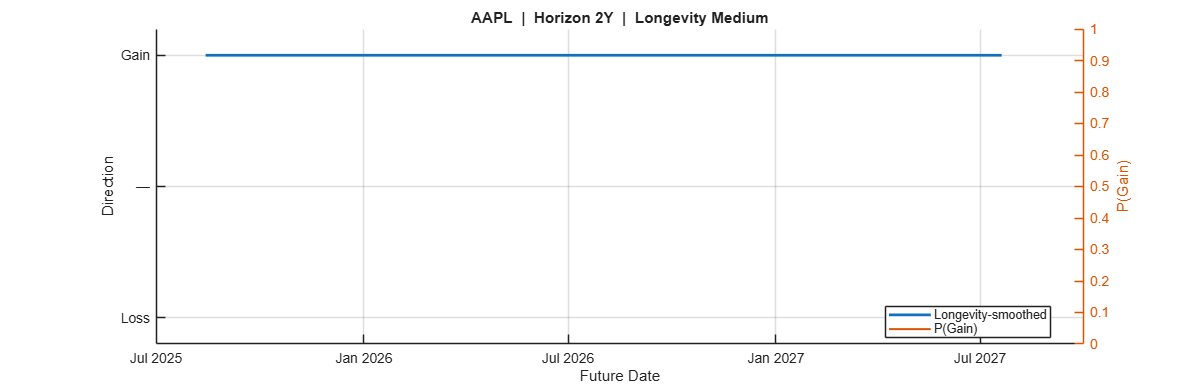


% ---------- Forecast Plot ----------
hfigF = getOrCreateFig("Forward Forecast", [240 120 1200 420]);
axF   = getOrCreateAxes(hfigF, "axForecast");
grid(axF,'on'); hold(axF,'on');
xlabel(axF,'Future Date'); ylabel(axF,'Direction');
title(axF, sprintf('%s  |  Horizon %s  |  Longevity %s', upper(string(ticker)), forecastHorizon, longevity));
set(axF,'YLim',[-1.2 1.2],'YTick',[-1 0 1],'YTickLabel',{'Loss','—','Gain'});
safeXLim(axF, futureDates);
stairs(axF, futureDates, dirSmoothed, 'LineWidth',2.0, 'DisplayName','Longevity-smoothed');
flipsSm   = find([false; diff(dirSmoothed)~=0] & ~isnan(dirSmoothed));
plot(axF, futureDates(flipsSm), dirSmoothed(flipsSm), 'o', 'MarkerSize',6, 'LineWidth',1.0, 'DisplayName','Flip points');

yyaxis(axF,'right');
plot(axF, futureDates, probUp, 'LineWidth',1.4, 'DisplayName','P(Gain)');
ylim(axF,[0 1]); ylabel(axF,'P(Gain)');
yyaxis(axF,'left');
legend(axF,'Location','best');

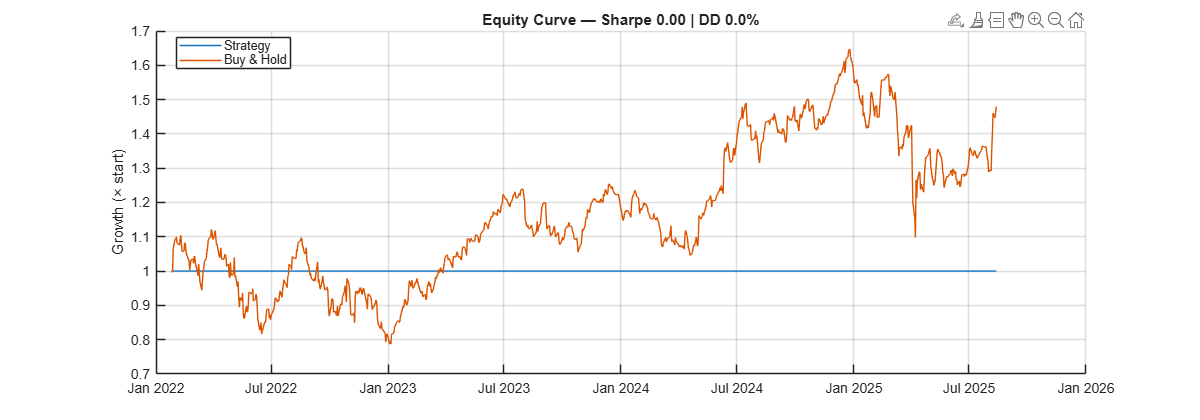


% ---------- Backtest Equity Curve ----------
hfigBT = getOrCreateFig("Backtest Equity", [260 160 1200 420]);
axBT   = getOrCreateAxes(hfigBT, "axBT");
cla(axBT); grid(axBT,'on'); hold(axBT,'on');
plot(axBT, R.dates, R.equity, 'DisplayName','Strategy');
plot(axBT, R.dates, R.market,  'DisplayName','Buy & Hold');
title(axBT, sprintf('Equity Curve — Sharpe %.2f | DD %.1f%%', R.sharpe, 100*R.mdd));
legend(axBT,'Location','best'); ylabel(axBT,'Growth (× start)');


%% ---------------------- Local functions ----------------------

function T = getHistory(ticker, startDT, endDT, interval)
    switch interval
        case "1d", i = "d";
        case "1wk", i = "w";
        case "1mo", i = "m";
    end
    sym = normalizeStooqSymbol(ticker);
    url = "https://stooq.com/q/d/l/?s=" + sym + "&i=" + i;
    try
        opts = detectImportOptions(url, 'NumHeaderLines', 0);
        opts = setvartype(opts, 'Date','datetime');
        present = intersect({'Open','High','Low','Close','Volume'}, opts.VariableNames, 'stable');
        opts = setvartype(opts, present, 'double');
        TT = readtable(url, opts);
    catch
        TT = readtable(url);
        if ismember('Date', TT.Properties.VariableNames)
            TT.Date = datetime(TT.Date);
        end
    end
    if isempty(TT) || ~ismember("Date", string(TT.Properties.VariableNames))
        T = table(); return
    end
    TT = rmmissing(TT);
    TT = sortrows(TT, 'Date');
    TT = TT(TT.Date >= startDT & TT.Date <= endDT, :);
    if ~ismember("AdjClose", string(TT.Properties.VariableNames))
        TT.AdjClose = TT.Close;
    end
    keep = intersect({'Date','Open','High','Low','Close','AdjClose','Volume'}, TT.Properties.VariableNames, 'stable');
    T = TT(:, keep);
end

function out = normalizeStooqSymbol(ticker)
    t = strtrim(lower(ticker));
    if contains(t, "."), out = t; return, end
    switch upper(ticker)
        case {"^GSPC","SPX","^SPX"}; out = "spy.us";
        case {"^NDX","NDX"};         out = "qqq.us";
        case {"^DJI","DJIA"};        out = "dia.us";
        otherwise;                   out = t + ".us";
    end
end

function y = ema_simple(x, N)
    x = x(:); y = nan(size(x));
    if isempty(x) || all(isnan(x)), return; end
    alpha = 2/(N+1); k0 = find(~isnan(x),1);
    if k0+N-1 <= numel(x), y(k0+N-1)=mean(x(k0:k0+N-1),'omitnan'); ks=k0+N;
    else, y(k0)=x(k0); ks=k0+1; end
    for k = ks:numel(x)
        if isnan(x(k)), y(k)=y(k-1); else, y(k)=alpha*x(k)+(1-alpha)*y(k-1); end
    end
end

function [mid, low, up] = boll_bands(x, N, K)
    mid = movmean(x, N, 'omitnan'); sd = movstd(x, N, 0, 'omitnan');
    up  = mid + K*sd; low = mid - K*sd;
end

function r = rsi_simple(x, N)
    dx = [NaN; diff(x(:))]; g = max(dx,0); l = max(-dx,0);
    avgG = movmean(g, N, 'omitnan'); avgL = movmean(l, N, 'omitnan');
    RS  = avgG ./ max(avgL, eps); r = 100 - (100 ./ (1 + RS));
end

function [macdLine, signalLine] = macd_simple(x, fastN, slowN, sigN)
    emaFast = ema_simple(x, fastN);
    emaSlow = ema_simple(x, slowN);
    macdLine = emaFast - emaSlow;
    signalLine = ema_simple(macdLine, sigN);
end

function atrVal = atr_simple(highP, lowP, closeP, N)
    tr = max([highP-lowP, abs(highP-[NaN; closeP(1:end-1)]), abs(lowP-[NaN; closeP(1:end-1)])],[],2);
    atrVal = movmean(tr, N, 'omitnan');
end

function drift = kalman_drift(x, qVar, rVar)
    n = numel(x); drift = nan(n,1);
    xHat = x(1); P = 1; % init
    for k = 1:n
        % Predict
        xHat = xHat; 
        P = P + qVar;
        % Update
        if ~isnan(x(k))
            K = P / (P + rVar);
            xHat = xHat + K * (x(k) - xHat);
            P = (1 - K) * P;
        end
        drift(k) = xHat;
    end
end

function F = make_features_for_model_v2(T, lags, qVar, rVar, interval)
    interval = string(lower(interval));
    % Scale factors: approximate bars-per-day: 1d=1, 1wk≈5d, 1mo≈21d
    switch interval
        case "1d",  sf = 1;
        case "1wk", sf = 5;
        case "1mo", sf = 21;
        otherwise,  sf = 1;
    end
    % Helper to shrink window lengths but keep >=3
    shrink = @(N) max(3, round(N/sf));

    closeP = T.AdjClose(:);
    ret1   = [NaN; diff(closeP)./closeP(1:end-1)];

    % Scaled windows
    N_SMA  = shrink(20);
    N_EMA  = shrink(50);
    N_BB   = shrink(20);
    K_BB   = 2;
    N_RSI  = shrink(14);
    % MACD classic 12/26/9 → shrink by sf
    N_MACD_FAST = shrink(12);
    N_MACD_SLOW = max(N_MACD_FAST+1, shrink(26)); % ensure slow>fast
    N_MACD_SIG  = shrink(9);
    % ATR classic 14 → shrink
    N_ATR  = shrink(14);

    % Indicators
    SMA    = movmean(closeP, N_SMA, 'omitnan');
    EMA    = ema_simple(closeP, N_EMA);
    RSI14  = rsi_simple(closeP, N_RSI);
    [BBmid, BBlow, BBup] = boll_bands(closeP, N_BB, K_BB);
    [macdLine, macdSignal] = macd_simple(closeP, N_MACD_FAST, N_MACD_SLOW, N_MACD_SIG);
    % Safe ATR inputs (proxy from AdjClose if OHLC are missing)
    vars = string(T.Properties.VariableNames);
    if all(ismember(["High","Low","Close"], vars))
        highP = T.High; lowP = T.Low; closeC = T.Close;
    else
        closeC = closeP; highP = closeP; lowP = closeP;
    end
    atrN = atr_simple(highP, lowP, closeC, N_ATR);
    drift  = kalman_drift(ret1, qVar, rVar);

    % Base features
    x_smaDist    = (closeP./SMA) - 1;
    x_bbPos      = (closeP - BBmid) ./ (BBup - BBlow + eps);
    x_rsi        = RSI14/100;
    x_emaOverSma = EMA ./ (SMA + eps) - 1;
    x_vol20      = movstd(ret1, shrink(20), 'omitnan'); % scaled
    x_macd       = macdLine;
    x_macdSignal = macdSignal;
    x_atr        = atrN ./ closeP;
    x_drift      = drift;

    % Lagged returns (scale the lags as well)
    lags = sort(unique(lags(:)'));
    for i = 1:numel(lags)
        Ls = max(1, round(lags(i)/sf)); % shrink lag in bars
        eval(sprintf('x_retLag%d = [nan(Ls,1); ret1(1:end-Ls)];', lags(i)));
    end

    y_ret = [ret1(2:end); NaN];
    y_dir = sign(y_ret); y_dir(y_dir==0) = -1;

    % --- Build FEATURES table first (no targets in the filter) ---
    F = table(T.Date, x_smaDist, x_bbPos, x_rsi, x_emaOverSma, x_vol20, ...
              x_macd, x_macdSignal, x_atr, x_drift, ...
              'VariableNames', {'Date','x_smaDist','x_bbPos','x_rsi','x_emaOverSma','x_vol20', ...
                                'x_macd','x_macdSignal','x_atr','x_drift'});

    % Add lag columns
    for i = 1:numel(lags)
        F.(sprintf('x_retLag%d', lags(i))) = eval(sprintf('x_retLag%d', lags(i)));
    end

    % Filter ONLY on feature columns (not targets)
    featNames = string(F.Properties.VariableNames);
    featNames = featNames(startsWith(featNames,"x_"));
    ok = all(~isnan(F{:,featNames}), 2);
    if nnz(ok) < 10
        % Be forgiving if interval is coarse; keep rows that have at least 80% features present
        ok = mean(~isnan(F{:,featNames}), 2) >= 0.8;
    end
    F = F(ok,:);

    % --- Now (re)compute targets aligned to filtered rows ---
    % Recompute on the filtered date index to be safe
    idx = ismember(T.Date, F.Date);
    closeF = T.AdjClose(idx);
    ret1F  = [NaN; diff(closeF)./closeF(1:end-1)];
    y_ret  = [ret1F(2:end); NaN];
    y_dir  = sign(y_ret); y_dir(y_dir==0) = -1;

    % Attach targets
    F.y_ret = y_ret;
    F.y_dir = y_dir;

end



function b = logit_train(X, y01, lambda)
    X = double(X); y = double(y01(:)); [n,p] = size(X);
    if n==0 || p==0, b=zeros(p,1); return; end

    % Drop near-const cols
    sd = std(X,0,1,'omitnan');
    keep = sd > 1e-12; Xr = X(:,keep); pr = size(Xr,2);
    map = find(keep);

    if pr==0, b=zeros(p,1); return; end

    lam = max(lambda, 1 + 10*(pr > n));
    I = eye(pr);
    b_r = zeros(pr,1);
    maxit = 50; tol = 1e-6;

    for it=1:maxit
        z  = Xr*b_r;
        ph = 1 ./ (1 + exp(-z));
        Wd = ph .* (1- ph) + 1e-6;         % avoid zeros
        H  = (Xr' * (Wd .* Xr)) + lam*I + 1e-9*I;

        % Solve Newton step via chol with fallback
        ok=false; tries=0; step=zeros(pr,1);
        while ~ok && tries<3
            try
                R = chol(H);
                g = Xr'*(ph - y) + lam*b_r;
                step = R \ (R' \ g);
                ok = true;
            catch
                lam = lam * 10; H = (Xr' * (Wd .* Xr)) + lam*I + 1e-9*I; tries=tries+1;
            end
        end
        if ~ok
            g = Xr'*(ph - y) + lam*b_r;
            step = pinv(H)*g;
        end

        b_new = b_r - step;
        if norm(b_new - b_r) < tol*(1+norm(b_r)), b_r = b_new; break; end
        b_r = b_new;
    end

    % Expand back to full p
    b = zeros(p,1); b(map) = b_r;
end



function s = sigmoid(z)
    s = 1 ./ (1 + exp(-z));
end

function [futureDates, dirRaw, dirSmoothed, probUp, model, varNames] = ...
    forecast_direction_upgraded(T, interval, horizonStr, longevity, ...
                                modelType, lags, qVar, rVar)

    F = make_features_for_model_v2(T, lags, qVar, rVar, interval);

    % Ensure enough rows remain after feature construction
    nF = height(F);
    if nF < 8
        error("Still too few rows after feature creation. Check interval/controls or try a different ticker.");
    end
    
    split = max(5, round(nF*0.8));
    split = min(split, nF-1);


    Tr = F(1:split,:);
    Xtr = Tr{:, startsWith(Tr.Properties.VariableNames,"x_")};
    y_ret_tr = Tr.y_ret; 
    y_dir_tr = (Tr.y_dir==1);

    [XtrS, mu, sig] = zscore(Xtr); 
    sig(sig==0)=1;

    % Train both models
    W = ridge_reg_train(XtrS, y_ret_tr, 0.5);
    b = logit_train(XtrS, y_dir_tr, 0.5);
    model = struct('kind',modelType,'W',W,'b',b,'mu',mu,'sig',sig,'lambda',0.5);

    nSteps = horizon_to_steps(horizonStr, interval);
    [futureDates, fClose, probUp] = rollout_with_model(T, interval, nSteps, model, lags, qVar, rVar);
    dirRaw = ones(nSteps,1); 
    dirRaw(probUp<0.5) = -1;

    switch string(longevity)
        case "Short",  win = max(1, round(nSteps*0.02));
        case "Medium", win = max(3, round(nSteps*0.10));
        case "Long",   win = max(5, round(nSteps*0.30));
    end
    dirSmoothed = majority_filter(dirRaw, win);
    varNames = string(F.Properties.VariableNames);
end


function [fDates, fClose, pGain] = rollout_with_model(T, interval, nSteps, model, lags, qVar, rVar)
    lastDate  = T.Date(end);
    closeSim  = T.AdjClose(:);
    fDates    = future_calendar(lastDate, interval, nSteps);
    pGain     = nan(nSteps,1);

    for k = 1:nSteps
        % Build a temp table with (history + k-1 future placeholders)
        futureSoFar = fDates(1:k-1);
        datesTemp   = [T.Date; futureSoFar];
        % Use the last known close as a placeholder for each future row
        closesTemp  = [closeSim; repmat(closeSim(end), max(0,k-1), 1)];

        % Build a temp table with (history + k-1 future placeholders)
        futureSoFar = fDates(1:k-1);
        datesTemp   = [T.Date; futureSoFar];
        
        % Use the last known close as a placeholder for each future row
        closesTemp  = [closeSim; repmat(closeSim(end), max(0,k-1), 1)];
        
        % Build a temp table with (history + k-1 future placeholders)
        futureSoFar = fDates(1:k-1);
        datesTemp   = [T.Date; futureSoFar];
        
        % Use the last known close as a placeholder for each future row
        closesTemp  = closeSim;
        
        Ttemp = table(datesTemp, closesTemp, 'VariableNames', {'Date','AdjClose'});
        % Provide OHLC proxies so ATR and other features work
        Ttemp.Close = closesTemp;
        Ttemp.High  = closesTemp;
        Ttemp.Low   = closesTemp;
        % Provide OHLC proxies so ATR and other features work
        Ttemp.Close = closesTemp;
        Ttemp.High  = closesTemp;
        Ttemp.Low   = closesTemp;


        % Features on expanded series
        Ftemp = make_features_for_model_v2(Ttemp, lags, qVar, rVar, interval);
        x     = Ftemp{end, startsWith(Ftemp.Properties.VariableNames,"x_")};
        xS    = (x - model.mu) ./ max(model.sig, eps);

        % Ensemble score → probability
        s      = tanh(5*(xS*model.W));
        pL     = sigmoid(xS*model.b);
        score  = 0.5*s + 0.5*(2*pL-1);   % [-1,1]
        pGain(k) = (score+1)/2;          % [0,1]

        % Roll one step forward
        retGuess = 0.003 * score;        % tiny step for smooth pathing
        nextClose = closeSim(end) * (1 + retGuess);
        closeSim  = [closeSim; nextClose];
    end

    fClose = closeSim(end-nSteps+1:end);
end

function R = backtest_walkforward(T, modelType, lags, lambda, threshLong, costBps, qVar, rVar, interval)
    costs = costBps/1e4;

    N = height(T);
    if N < 5
        % Degenerate case: return empty-ish but valid struct
        R = struct('dates',T.Date,'ret',zeros(0,1),'pos',zeros(0,1),'pHat',zeros(0,1), ...
                   'equity',ones(0,1),'market',ones(0,1), ...
                   'sharpe',NaN,'hit',NaN,'mdd',0,'costBps',costBps,'thresh',threshLong);
        return;
    end

    maxHist = min(5000, N-2);
    iStart  = max(1, N - maxHist + 1);

    dates = T.Date(iStart:end);
    px    = T.AdjClose(iStart:end);
    ret1  = [NaN; diff(px)./px(1:end-1)];

    pHat  = nan(size(px));
    dirSig= nan(size(px));

    % Start prediction once we have a bit of history
    startI = min( max(30, 3), numel(px)-1 );  % at least 30 bars if available
    for i = startI:numel(px)-1
        TrTemp = table(dates(1:i), px(1:i), 'VariableNames', {'Date','AdjClose'});
        % Provide OHLC proxies so ATR works even if missing
        TrTemp.Close = TrTemp.AdjClose;
        TrTemp.High  = TrTemp.AdjClose;
        TrTemp.Low   = TrTemp.AdjClose;

        F = make_features_for_model_v2(TrTemp, lags, qVar, rVar, interval);
        if height(F) < 8
            continue; % not enough features yet
        end

        split = max(5, height(F)-40);
        Tr = F(1:split,:);
        X  = Tr{:, startsWith(Tr.Properties.VariableNames,"x_")};
        yR = Tr.y_ret; yD = (Tr.y_dir==1);
        [Xs, mu, sig] = zscore(X); sig(sig==0)=1;

        % Train ensemble
        W   = ridge_reg_train(Xs, yR, lambda);
        b   = logit_train(Xs, yD, lambda);

        % Score the last point
        Fnow = make_features_for_model_v2(TrTemp, lags, qVar, rVar, interval);
        x    = Fnow{end, startsWith(Fnow.Properties.VariableNames,"x_")};
        xS   = (x - mu)./max(sig,eps);

        s     = tanh(5*(xS*W));
        pL    = sigmoid(xS*b);
        score = 0.5*s + 0.5*(2*pL-1);
        p     = (score+1)/2;

        pHat(i)   = p;
        dirSig(i) = (p >= threshLong);   % 1=long, 0=flat
    end

    % Strategy series (robust to NaNs/empties)
    pos   = fillmissing(dirSig,'constant',0);
    if numel(pos) ~= numel(ret1), pos = zeros(size(ret1)); end
    chg   = [0; diff(pos)];
    gross = pos .* ret1;
    net   = gross - abs(chg)*costs;

    if isempty(net) || all(~isfinite(net))
        net = zeros(max(1,numel(ret1)),1);
    end

    eq  = cumprod(1 + fillmissing(net,'constant',0));
    if isempty(eq), eq = 1; end
    mkt = cumprod(1 + fillmissing(ret1,'constant',0));
    if isempty(mkt), mkt = 1; end

    % Metrics (safe)
    ann = 252;
    if any(isfinite(net))
        mu  = nanmean(net)*ann;
        sd  = nanstd(net)*sqrt(ann);
        sharpe = mu / max(sd, eps);
    else
        sharpe = NaN;
    end
    if any(isfinite(ret1)) && any(isfinite(pos))
        hit = mean( (ret1>0) == (pos>0) ,'omitnan');
    else
        hit = NaN;
    end
    dd  = maxdrawdown(eq);

    R = struct('dates',dates,'ret',net,'pos',pos,'pHat',pHat,'equity',eq,'market',mkt, ...
               'sharpe',sharpe,'hit',hit,'mdd',dd,'costBps',costBps,'thresh',threshLong);
end


function d = maxdrawdown(eq)
    % Robust: handle empty / NaN inputs gracefully
    if nargin==0 || isempty(eq)
        d = 0; return;
    end
    eq = eq(:);
    eq = eq(isfinite(eq));
    if isempty(eq)
        d = 0; return;
    end
    peak = eq(1); d = 0;
    for i = 1:numel(eq)
        if eq(i) > peak, peak = eq(i); end
        draw = eq(i)/peak - 1;
        if draw < d, d = draw; end
    end
    d = abs(d);
end


function dates = future_calendar(lastDate, interval, nSteps)
    dates = NaT(nSteps,1);
    switch interval
        case "1d"
            d = lastDate;
            for i=1:nSteps
                d = d + days(1);
                while isweekend(d), d = d + days(1); end
                dates(i) = d;
            end
        case "1wk"
            for i=1:nSteps, dates(i) = lastDate + calweeks(i); end
        case "1mo"
            for i=1:nSteps, dates(i) = lastDate + calmonths(i); end
    end
end

function n = horizon_to_steps(hStr, interval)
    switch upper(hStr)
        case "1M", months = 1;
        case "3M", months = 3;
        case "6M", months = 6;
        case "1Y", months = 12;
        case "2Y", months = 24;
        otherwise, months = 12;
    end
    switch lower(interval)
        case "1d",  n = round(months*21);   % ~21 trading days/month
        case "1wk", n = round(months*4.3);  % weeks/month
        case "1mo", n = months;
    end
    n = max(2, n);   % <-- ensure at least 2
end


function y = majority_filter(x, win)
    x = x(:);
    if win<=1, y = x; return, end
    half = floor(win/2);
    y = nan(size(x));
    for i=1:numel(x)
        i1 = max(1, i-half); i2 = min(numel(x), i+half);
        seg = x(i1:i2); seg = seg(~isnan(seg));
        if isempty(seg), y(i)=x(i); continue, end
        if sum(seg==1) >= sum(seg==-1), y(i)=1; else, y(i)=-1; end
    end
end

function [px,py] = bandPolygon(t, ylo, yhi)
    t = t(:); ylo = ylo(:); yhi = yhi(:);
    ok = ~(ismissing(t) | ismissing(ylo) | ismissing(yhi));
    t = t(ok); ylo = ylo(ok); yhi = yhi(ok);
    if numel(t) < 2, px = nan; py = nan; return; end
    px = [t; flipud(t)];
    py = [ylo; flipud(yhi)];
end

function f = getOrCreateFig(name, pos)
    f = findall(0,'Type','figure','Name',name);
    if isempty(f) || ~isvalid(f)
        f = figure('Color','w','Name',name,'NumberTitle','off','Position',pos,'Visible','on');
    else
        try, set(f,'Position',pos,'Visible','on'); catch, end
    end
end

function ax = getOrCreateAxes(fig, tagName)
    ax = findobj(fig,'Type','axes','-and','Tag',tagName);
    if isempty(ax) || ~isvalid(ax(1))
        ax = axes('Parent',fig,'Tag',tagName);
    else
        ax = ax(1);
    end
end

function W = ridge_reg_train(X, y, lambda)
    % Clean rows
    good = ~any(isnan(X),2) & ~isnan(y);
    X = double(X(good,:)); y = double(y(good));
    [n,p] = size(X);
    if n==0 || p==0, W = zeros(p,1); return; end

    % Zeros / near-const cols
    sd = std(X,0,1,'omitnan');
    keep = sd > 1e-12;
    Xr = X(:,keep); pr = size(Xr,2);

    % Drop near-duplicate cols (|corr| > 0.999)
    if pr > 1
        C = corr(Xr, 'rows','pairwise');
        C(1:pr+1:end) = 0;                  % zero diagonal
        dup = false(1,pr);
        for j=2:pr
            if any(abs(C(1:j-1,j)) > 0.999), dup(j)=true; end
        end
        Xr = Xr(:,~dup);
        map = find(keep); map = map(~dup);
    else
        map = find(keep);
    end
    pr = size(Xr,2);

    % If nothing left, return zeros
    if pr==0, W = zeros(p,1); return; end

    % Auto-regularization: stronger if p>n
    lam = max(lambda, 1 + 10*(pr > n));

    % Build normal matrix
    A = Xr.'*Xr;

    % Try Cholesky with escalating ridge if needed
    ok = false; tries = 0;
    while ~ok && tries < 5
        try
            R = chol(A + lam*eye(pr) + 1e-9*eye(pr));
            Wr = R \ (R' \ (Xr.'*y));
            ok = true;
        catch
            lam = lam * 10; tries = tries + 1;
        end
    end
    if ~ok
        % Final safe fallback
        Wr = pinv(A + lam*eye(pr)) * (Xr.'*y);
    end

    % Expand back to full p
    W = zeros(p,1);
    W(map) = Wr;
end


function safeXLim(ax, x)
    try
        x = x(:);

        if isdatetime(x)
            % Remove NaT and duplicates, sort
            x = x(~isnat(x));
            if numel(x) == 0
                xlim(ax,'auto'); return;
            end
            x = unique(x,'sorted');

            if numel(x) == 1
                % Create a minimal span
                xl = [x(1), x(1) + days(1)];
            else
                xl = [x(1), x(end)];
                if xl(2) <= xl(1)
                    xl(2) = xl(1) + days(1);
                end
            end

            % Final sanity: must be strictly increasing datetimes
            if ~isdatetime(xl) || any(isnat(xl)) || xl(2) <= xl(1)
                xlim(ax,'auto'); return;
            end
            xlim(ax, xl);
        else
            % Numeric case
            x = x(isfinite(x));
            if numel(x) == 0
                xlim(ax,'auto'); return;
            end
            x = unique(x,'sorted');

            if numel(x) == 1
                xl = [x(1), x(1) + eps(x(1))];
            else
                xl = [x(1), x(end)];
                if xl(2) <= xl(1)
                    xl(2) = xl(1) + max(eps(xl(1)), 1e-12);
                end
            end

            if ~isfinite(xl(1)) || ~isfinite(xl(2)) || xl(2) <= xl(1)
                xlim(ax,'auto'); return;
            end
            xlim(ax, xl);
        end
    catch
        % Absolute safety net
        xlim(ax,'auto');
    end
end

